## Blink using Arduino, LED, Live Script & Controls

### Basic Blink Code to modify

% Arduino Blink
clc
clear
m=arduino('com3','Mega2560');
for i=1:20
    writeDigitalPin(m,'D7',1);
    pause(1);
    writeDigitalPin(m,'D7',0);
    pause(1);
end

### Example Controls:

% Win (cmd) shift S in windows 10 for a Mac like screenshot tool
%% on MacBook Pro using Boot Camp to Windows 10

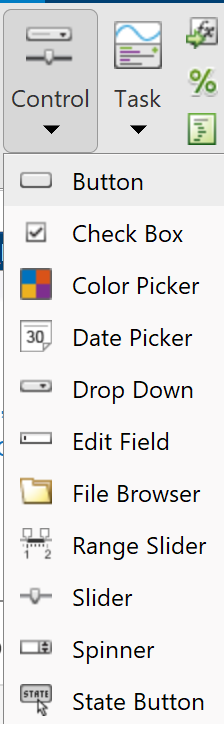

#### Change # loops

clc
clear
i=0;

kk=[5 20];
m=arduino('com3','Mega2560');
kk

kk =      5    20


while i < kk(1, 1) % not good to usse for i=1:kk as wants value
    writeDigitalPin(m,'D7',1);
    pause(1);
    writeDigitalPin(m,'D7',0);
    pause(1);
    i=i+1;
end
pause (10)
clear % reset mega

#### Change delays – on or off

% Arduino Blink
clc
clear
p=0;
p=0.2

p = 0.2000

m=arduino('com3','Mega2560');
for i=1:10
    writeDigitalPin(m,'D7',1);
    pause(p);
    writeDigitalPin(m,'D7',0);
    pause(p);
end
clear 

#### Change LED brightness

% Send pulse signals of specified width to the PWM pins on the Arduino 
% hardware. PWM signals can light up LEDs connected to the pin. The duty
% cycle of the pulse controls the brightness of the LED. Calculate the
% amount that the LED brightens and dims by dividing the max and min duty
% cycle for the pin by the number of iterations.
% The expression (1-0)/20) simplifies to (1/20), which is (0.05) or (5%).

% brightness_step = CONTROL ??
clear
a=arduino('com3');
  brightness_step = 0.05; % was (1-0)/20;
   % Brighten
        for i = 1:20
            writePWMDutyCycle(a, 'D7', i * brightness_step);
            pause(0.1);
        end
    % Dim
        for i = 1:20
            writePWMDutyCycle(a, 'D7', 1 - i * brightness_step);
            pause(0.1);
        end
% clear